# Nonlinear Centers: The Hare-Lynx Example

Use this script to plot the numeric solution to the hare-lynx example from the final project part 1. Your tasks are to:

- Choose three sets of initial conditions that are not critical points. Currently all initial conditions are set to [0,0].

- Set the endtime to solve the equation in the variable tspan so that you can visually determine that the solution is a closed orbit. You will do this using the drop down menu in line 2 of the code. 

- Vary the parameter **a** to see how the plots change. Watch out for changing **a** such that one of your initial conditions becomes a critical point!

- **Bonus: **Modify line 6 and change the tolerances for the numeric solver and see the results.

## Set parameters for the system of ODEs

All the initial conditions are currently set to the critical point, [0, 0]. Change them and run the code to view the results. Then change the end time in **tspan **to prove to yourself that all solutions are closed orbits. Vary **a** to see the effect on the solution.

IC_1 = [2; 1];
IC_2 = [2; 6];
IC_3 = [3; 3];
tspan = [0, 10];
a = 0.75;

## Solve the system of ODEs for the three different sets of initial conditions

*You do not need to edit the code below*, it is completed for you. First we set the tolerances for the ODE45 function to ensure we see closed orbits. Then the ODE45 function is used to solve the system of diffential equations, and finally we plot the solutions. 

**Bonus**: Change the tolerances in line 6 to something smaller (like 1e-3) and tspan to a large value. What do you see? Is the orbit closed, stable spiral, unstable spiral? It is important to have a physical intuition to how the solutions to ODEs look. Numerical solvers produce approximate solutions that vary from the real solution. In some cases, we need to manually set the tolerance of the solver to ensure an accurate solution, at the expense of computational times. In other situations, we may need to even[ choose a different solver](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html), or code our own!

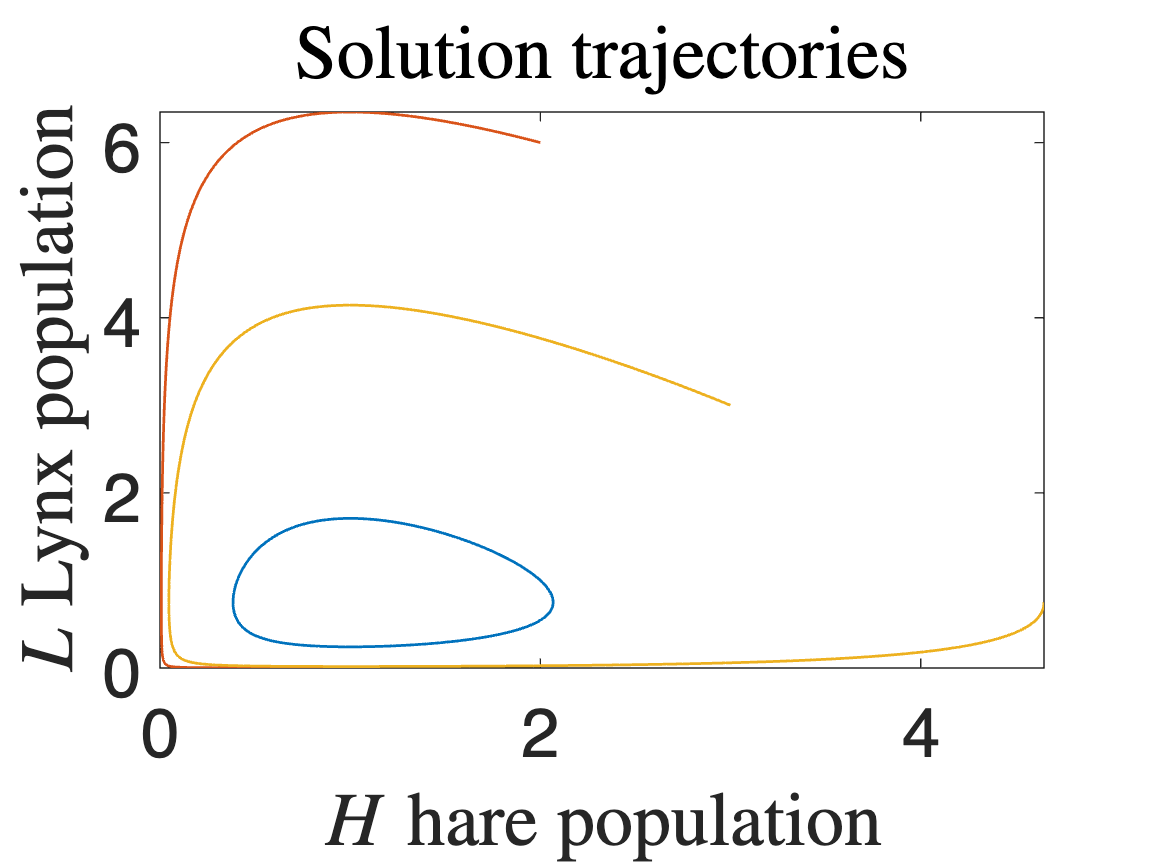

opts = odeset('AbsTol', 1e-7, 'RelTol', 1e-7);
odefun = @(t,x) hareLynx(t,x,a);
[t1, sol1] = ode45(odefun, tspan, IC_1, opts);
[t2, sol2] = ode45(odefun, tspan, IC_2, opts);
[t3, sol3] = ode45(odefun, tspan, IC_3, opts);
plot(sol1(:,1),sol1(:,2), 'LineWidth', 1)
hold on
plot(sol2(:,1), sol2(:,2), 'LineWidth', 1)
plot(sol3(:,1), sol3(:,2), 'LineWidth', 1)
xlabel('$H$ hare population','interpreter','latex')
ylabel('$L$ Lynx population','interpreter','latex')
title('Solution trajectories','interpreter','latex')
set(gca,'fontsize',25)
%legend({mat2str(IC_1), mat2str(IC_2), mat2str(IC_3)})
hold off

## Create the ODE function. 

This helper function that returns the system of ODEs to pass to ODE45. **x** is a two element vector [H; L] where:


$$\dot H = aH - HL$$
 


$$\dot L = -L + HL$$


function odefun = hareLynx(t, x, a)
    H = x(1);
    L = x(2);
    dH = a*H - H*L;
    dL = -L + H*L;
    odefun = [dH; dL];
end